% clean up
clear all

## **Steady State Experiment (Temp. as function of distance)**

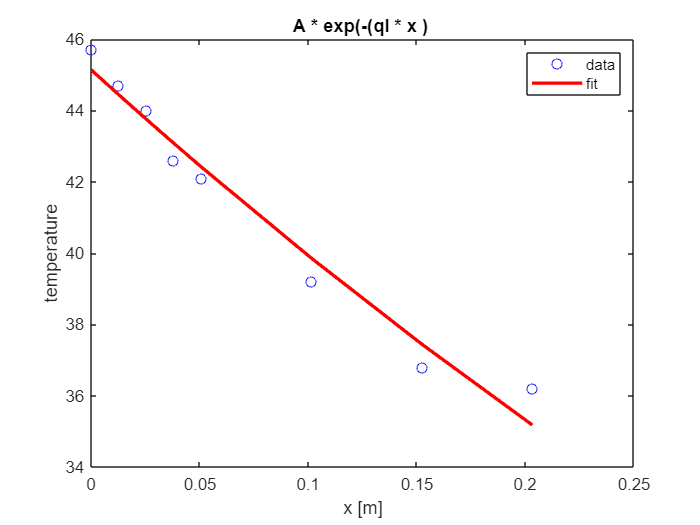

dataY = [45.7 44.7 44.0 42.6 42.1 39.2 36.8 36.2]';

dataX = [0 12.7e-3 25.4e-3 38.1e-3 50.8e-3 101.6e-3 152.4e-3 203.2e-3]';

steadyStateEq = fittype('A * exp(-(ql * (x)) )', 'independent', 'x','coefficients', {'A', 'ql'});

[steadyStateFit, steadyStateGof] = fit(dataX, dataY, steadyStateEq, 'StartPoint', [43 4]);

% plot the data and fit

    % Plot the data points
    plot(dataX, dataY, 'bo', 'DisplayName', 'Data');
    hold on;

    % Calculate the fit values based on the model
    A = steadyStateFit.A;
    ql = steadyStateFit.ql;

    % Generate the fit curve using the model
    fitCurve = A * exp(-(ql * (dataX)) );

    % Plot the fit curve
    plot(dataX, fitCurve, 'r-','LineWidth', 2, 'DisplayName', 'Fit');

    % Label the plot
    title(['A * exp(-(ql * x ) ']);
    xlabel('x [m]');
    ylabel('temperature');
    legend('data', 'fit');

    hold off;

## Angstrom experiment

Works with TEC_V7.mlapp & SerialTestNov1a.ino which sinusoidally varies Tset and measures the temperature at multiple locations along a cylinder of metal.

PlotAngstromExpPeriod60.mlx extracts the temperature at 3 locations plus at the TEC vs time data for sinusoidally varying Tset. Add 2 more thermistors and extend code to measure at 5 locations plus TEC.

All the Arduino controls are printed whenever a control parameter is changed. This information be used to find the time intervals over which the Tset parameters did not change for analysis of the steady state temperature distribution along the rod.

#### All this code was written with a lot of help from ChatGPT. However, it took quite a few iterations to get exactly what I wanted. There is no way I could have done this on my own as my Matlab skills are weak. Nevertheless, some knowledge of Matlab structure and coding was necessary, as well as having a sense of what is possible.

% Define the filenames
filenames = {"C:\Users\1samk\OneDrive - brandeis.edu\College2023-24\College2023-24Fall\Lab\PHSY39-ThermControl\ThermalConductivPeriod100.txt"
    "C:\Users\1samk\OneDrive - brandeis.edu\College2023-24\College2023-24Fall\Lab\PHSY39-ThermControl\ThermalConductivPeriod130.txt"
    "C:\Users\1samk\OneDrive - brandeis.edu\College2023-24\College2023-24Fall\Lab\PHSY39-ThermControl\ThermalConductivPeriod160.txt"
    "C:\Users\1samk\OneDrive - brandeis.edu\College2023-24\College2023-24Fall\Lab\PHSY39-ThermControl\ThermalConductivPeriod190.txt"
    "C:\Users\1samk\OneDrive - brandeis.edu\College2023-24\College2023-24Fall\Lab\PHSY39-ThermControl\ThermalConductivPeriod220.txt"};
periods = [100 130 160 190 220];

allData = configureDictionary("int64","cell");

for fileNum = 1:length(filenames)
    filename = filenames{fileNum};

    % Read the entire file as text
    fileID = fopen(filename, 'r');
    allLines = textscan(fileID, '%s', 'Delimiter', '\n');
    fclose(fileID);
    
    % Separate lines with text from lines with numerical data
    textLines = {};
    numericData = [];
    
    for i = 1:numel(allLines{1})
        line = allLines{1}{i};
        if any(isletter(line))  % Check if the line contains letters (text)
            textLines{end + 1} = line;
        else
            numericValues = str2num(line);
            if ~isempty(numericValues) && numel(numericValues) == 9
                numericData = [numericData; numericValues];
            end
        end
    end
    
    % Convert textLines to a string array
    textData = string(textLines);
    
    % Display text lines on separate lines
    % Use this information to set the time limits to extract data in the next section
    for i = 2:numel(textData)
        fprintf('%s\n', textData(i));
    end
    % Example: Display the first few lines of numeric data
    if true
        fprintf('%s\n', textData(1));
        disp(numericData(1:5, :));
    end
    
    allData(periods(fileNum))={numericData};

end

Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
Sin	17.4	236	1		20.0	1.0	40.0		1		20.0		100.0


Temperature	PWM	Time	Set Temperature	T1	T2	T3	T4	T5


   20.6800 -217.0000   79.5000   20.7900   32.2700   33.6200   36.5100   36.1500   35.3400
   20.1200 -188.0000   80.6000   21.2100   31.7800   33.2000   36.2900   36.0500   35.3100
   19.7300 -160.0000   81.6000   21.7100   31.3100   32.7700   36.0700   35.9500   35.2600
   19.5000 -133.0000   82.7000   22.3000   30.8300   32.3400   35.8400   35.8200   35.2100
   19.4200 -106.0000   83.8000   22.9700   30.3800   31.9400   35.6100   35.7100   35.1600



Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
Sin	20.6	255	1		20.0	1.0	40.0		1		20.0		130.0


Temperature	PWM	Time	Set Temperature	T1	T2	T3	T4	T5


   35.5300 -214.0000   75.2000   30.5200   40.9600   40.9100   39.4000   37.4100   35.9900
   34.6100 -221.0000   76.3000   29.6200   40.5400   40.5800   39.3100   37.4000   36.0100
   33.6900 -227.0000   77.4000   28.7500   40.1200   40.2500   39.2100   37.3800   36.0300
   32.7800 -233.0000   78.4000   27.9100   39.6800   39.8900   39.1000   37.3700   36.0400
   31.8700 -237.0000   79.5000   27.1000   39.2200   39.5200   38.9900   37.3400   36.0600



Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
Sin	19.6	255	1		20.0	1.0	40.0		1		20.0		160.0


Temperature	PWM	Time	Set Temperature	T1	T2	T3	T4	T5


   66.4100   91.0000   53.8000   57.1200   47.6500   44.4500   35.0100   31.9800   31.2600
   65.8700   83.0000   54.9000   56.6700   48.0500   44.8600   35.3300   32.1500   31.3500
   65.3100   75.0000   56.0000   56.1900   48.4000   45.2300   35.6600   32.3400   31.4400
   64.7400   67.0000   57.0000   55.6800   48.6900   45.5600   35.9900   32.5300   31.5400
   64.1500   58.0000   58.1000   55.1500   48.9400   45.8500   36.3000   32.7100   31.6400



Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
Sin	65.9	255	1		20.0	1.0	40.0		0		20.0		190.0


Temperature	PWM	Time	Set Temperature	T1	T2	T3	T4	T5


   46.5600   17.0000   86.2000   45.7200   38.9600   37.3100   32.1300   30.2000   29.7900
   46.0700   12.0000   87.3000   45.0400   39.0300   37.4100   32.3000   30.3200   29.8600
   45.5600    8.0000   88.4000   44.3600   39.0800   37.4900   32.4500   30.4400   29.9300
   45.0400    3.0000   89.4000   43.6600   39.1000   37.5500   32.6100   30.5500   30.0000
   44.5000   -3.0000   90.5000   42.9700   39.0900   37.6000   32.7600   30.6600   30.0700



Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
Sin	23.9	255	1		20.0	1.0	40.0		0		20.0		220.0


Temperature	PWM	Time	Set Temperature	T1	T2	T3	T4	T5


   54.7200  166.0000   41.0000   58.4300   37.7200   35.8900   30.8700   30.1100   30.5400
   55.2900  163.0000   42.1000   58.6600   38.2600   36.3700   31.1000   30.2000   30.5500
   55.8100  160.0000   43.2000   58.8700   38.8000   36.8500   31.3400   30.2800   30.5600
   56.2900  157.0000   44.2000   59.0600   39.3200   37.3200   31.5800   30.3700   30.5700
   56.7500  154.0000   45.3000   59.2400   39.8400   37.7700   31.8100   30.4700   30.6000



## Plot temperature vs time

format of the data: *numericData* has n rows and 7 columns whose values are

          Temperature→PWM→Time→Set Temperature→T1→T2→T3

Temperature = col. 1 = TEC thermistor (C)

T1 = col. 5 = lowest thermistor  (C)

T2 = col. 6 = middle thermistor  (C)

T3 = col. 7 = highest thermistor (C)

time = col. 3 = elapsed time (seconds)

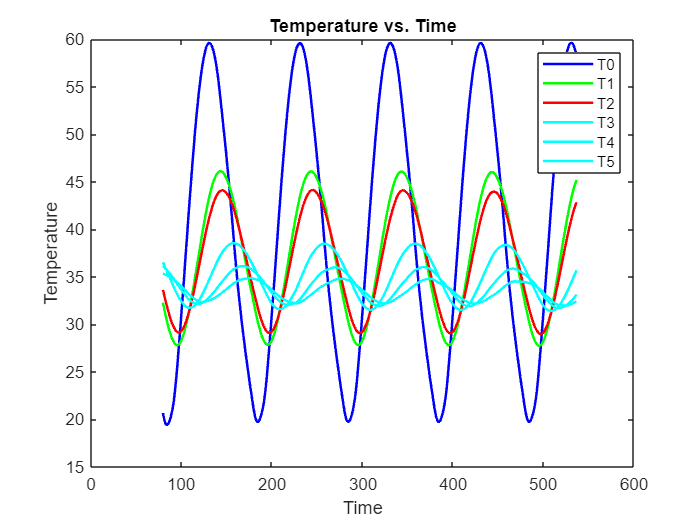

% enter period of oscillation
period = 100; % period of oscillation in seconds

numericData = allData{period};

% Define the lower and upper time limits of a time interval in which
%    control parameters were constant.
% let's plot all the data to see how it looks.

% Extract the 4 thermistors data within the time range
tempDataInRange = numericData(:, [1 5 6 7 8 9]);
time = numericData(:,3);

% Plot the temperature data vs time
plot(time, tempDataInRange(:, 1), 'b', 'LineWidth', 1.5); % TEC thermistor
hold on;
plot(time, tempDataInRange(:, 2), 'g', 'LineWidth', 1.5); % T1
plot(time, tempDataInRange(:, 3), 'r', 'LineWidth', 1.5); % T2
plot(time, tempDataInRange(:, 4), 'c', 'LineWidth', 1.5); % T3
plot(time, tempDataInRange(:, 5), 'c', 'LineWidth', 1.5); % T4
plot(time, tempDataInRange(:, 6), 'c', 'LineWidth', 1.5); % T5
hold off;
% Add labels and legend
xlabel('Time');
ylabel('Temperature');
title('Temperature vs. Time');
legend('T0', 'T1', 'T2', 'T3', 'T4', 'T5');

#### Analysis

In this experiment you will measure the steady-state temperature profile of a metal rod you will also measure the oscillatory temperature profile of a thin rod. The boundary conditions are that the base of the rod is $T_{\textrm{set}}$ and the rod is in a room with temperature $T_{\infty }$.

- Read Lienhard & Lienhard chapters 1.3 & 4.5. Focus on section 4.5 - temperature profile of a thin fin.

- For the derivation of the Angstrom experiment, with a periodically varying temperature, read Carslaw and Jaeger, sec. 4.4 pl. 136 -139. The semi-infinite rod.  

- Read Angstrom's 1863 paper.

- Read the paper by Zhang et. al. on the Angstrom experiment. 

- Read the student report from the College of Wooster of Angstrom's experiment.

The heat diffusion equation describes the spatial-temporal distribution of temperature in matter.

         
$$\frac{\partial T}{\partial t}=\frac{k}{c \rho }



\frac{\partial ^2T}{\partial x^2}-\frac{H P}{c \rho A  }T=\kappa  \frac{\partial ^2T}{\partial x^2}-\nu  T$$


In steady state


$$\frac{\partial T}{\partial t}=\kappa  \frac{\partial ^2T}{\partial x^2}-\nu  T = 0$$


and


$$T(x) = T(0)e^{-q_lx}$$


with


$$q_l=\sqrt{\frac{\nu }{\kappa }} = \sqrt{\frac{HP}{k A}}$$
 

Angstrom periodically varied the temperature at the base of the rod and solved the time dependent heat equation assuming a solution of the form


$$T\left(x,t\right)=T\left(x\right)e^{i\omega t}$$


Then


$$\frac{\partial ^2T}{\partial x^2} - \frac{\nu +i\omega}{\kappa}T = 0$$


The solution of this is


$$T(x) =T(0)e^{-qx - iq'x}$$


and if the temperature at the base is sinusoidally varied about room temperature, then


$$T(x,t) =T(0)e^{-qx}\cos(\omega t -q'x+\epsilon)$$


where


$$q + iq' = \sqrt{\frac{\nu + i\omega}{\kappa}}$$


with


$$q=\sqrt{\frac{\sqrt{\nu ^2+\omega ^2}+\nu }{2 \kappa }}$$



$$

q'=\sqrt{\frac{\sqrt{\nu ^2+\omega ^2}-\nu }{2 \kappa }}$$


and


$$q q'=\frac{\omega }{2 \kappa }$$


Units are M, kg, sec, Watts, J, K etc.

$d\;\left\lbrack M\right\rbrack$  diameter of rod

$H\;\left\lbrack \frac{\mathrm{W}}{{\mathrm{M}}^{2\;} \mathrm{K}}\right\rbrack$surface conductance

$k\;\left\lbrack \frac{\mathrm{W}}{\mathrm{M}\;\mathrm{K}}\right\rbrack$thermal conductivity

$P\;\left\lbrack \mathrm{M}\right\rbrack$ perimeter

$A\;\left\lbrack {\mathrm{M}}^2 \right\rbrack$ area

$\rho \;\left\lbrack \frac{\textrm{kg}}{{\mathrm{M}}^3 }\right\rbrack$ density

$c\;\left\lbrack \frac{J}{K\;\textrm{kg}\;}\right\rbrack$ specific heat

$v=\frac{H P}{c \rho A } [1/\text{sec}]$ thermal loss rate

$\kappa =\frac{k}{c \rho } \left[\frac{M^2}{\text{sec}}\right]$  thermal diffusion constant

#### values for aluminum

$\rho =2700\;\left\lbrack \frac{\textrm{kg}}{{\mathrm{M}}^3 }\right\rbrack \;\;\;$density

$c=900\;\left\lbrack \frac{J}{K\;\textrm{kg}}\right\rbrack$   specific heat

$d=\frac{1}{2\;}\textrm{inch}$ diameter

At the base of the rod apply the following time-dependent boundary condition:

              
$$\tau (0,t)=T_0+\text{$\Delta $T} \cos (\text{$\omega $t})$$


The solution for the difference in the temperature of the rod, $T\left(x,t\right)$, and lab, $T_{\infty }$,  is 

              
$$T

(

\text{\textit{x,t}}

\text{) - }

T_{\infty }

\text{ = $\tau $(}

x

,

t

\text{) = }

\left(T_0-T_{\infty }\right) e^{ -q_l x}+\text{$\Delta $T} e^{-q x} \cos \left(\omega t- q' x \right)$$


What happens for the non-oscillatory case of $\omega$ = 0? 

### Assignment

(0) How good are the thermistors? Are they repeatable? How much variability is there between them? How do you check? Where is the error coming from? The thermistors themselves, or fixed resistors, or the A/D conversion? How can you correct for the errors?

(1) Do the steady-state experiment by setting the base temperature to 60C and measuring the temperature along the rod. This is the experiment described by Abu-Mulaweh and in sec. 4.5 in Lienhard & Lienhard.

(2) Plot experiment and theory and obtain $\frac{1}{q_l }$.

(3) For the derivation of the Angstrom experiment with a periodically varying temperature, read [Carslaw and Jaeger, sec. 4.4 pl. 136 -139](http://216.92.172.113/courses/phys39/Thermal%20Measurement/conduction-of-heat-in-solids-carslaw-and-jaeger.pdf). The semi-infinite rod.

(4) First, use only proportional control and carefuly observe the temporally sinusoidal varying temperature. You will notice that the heating and cooling portions of the temperature are different. You observed that dT / dPWM was different for heating and cooling. Can you figure out how to modify the Arduino code to correct this and make the temperature profile closer to a sinusoid? --> see arduino code line 272

(5) Next, use integral control on the sinusoidal varying temperature profile. Under what conditions will the measured temperature accurately track the set temperature? What temperature amplitudes and period? (answer: when variational period is larger than responce time of system things temp acurately tracks set temp) Does it matter that dT / dPWM is different for heating and cooling when using integral control?(no)  

(6) Now do the oscillatory case. Set $T_{0\;} =$45 C. Oscillate temp with an amplitude of 10 degrees and a period between 60 s and 240 s, say 60, 120, 180, 240 seconds for the 1/2 inch diameter aluminum rod. To simplify results you can set $T_{0\;} =T_{\infty }$, but you probably should adjust the amplitude. How well does your controller perform? Tweak the PID settings to optimize temperature. Measure the temperature at 3 to 5 locations starting with the lowest hole near the bottom of rod. Make sure that the amplitude of the smallest measured temperature is at least 1C. (options that worked: kp=20 ki=1, setTemp=35 period=180 amp=20 or settemp=40 period=180 amp=20) Check that rod is at room temp at tip. Ideally, one would fit all data sets simultaneously to model, which has a bunch of fit parameters. Vary period and see if same thermal conductivity results are obtained. 

For each position, $x_i$, wait until the temperature settles into a periodic state and the base stops drifting. Collect data for at least 5 periods. 

 (7a) Fit the oscillating temperature to

                                   $T(x_i,t)=A_i+B_i \cos  \left( \omega t + \epsilon _i\right)$.

Say you measure at 4 positions, $x_i$. Then fit the 4 values of $A_i$, $B_i$ and $\varepsilon_i$.

$
A_i = 
(T_0-T_{\infty }) e^{- q_lx_i + \delta }  \text{ with }

q_l=\sqrt{\frac{\nu }{\kappa }}$ ,

$\delta$ is just some constant since we don't exactly know where the zero point is located. For now, we take the first thermistor located in the rod, above the TEC as location of the base of the rod, that is$\;\textrm{at}\;x_2 =0,$ $\delta =0$.   

$B_i = 

\text{$\Delta $T} e^{ -q x_i + \delta}

\text{ with }

q=\sqrt{\frac{\sqrt{\nu ^2+\omega ^2}+\nu }{2 \kappa }}$,  

and

$\epsilon_i = \epsilon -q' x_i 

\text{ with }

q'=\sqrt{\frac{\sqrt{\nu ^2+\omega ^2}-\nu }{2 \kappa }}$.  

$\varepsilon$ is just some constant since we don't exactly know when was the beginning of the experiment so we don't know the initial phase of the oscillation.

(7b) Make separate plots for the data and fits to temperature vs time for each thermistor.

(7c) Calculate $\kappa \;\textrm{and}\;\nu$. Note that $q q'=\frac{\omega }{2 \kappa }$! 

Once you have $\kappa$ you can get $\nu$. Now repeat as a function of frequency $\omega$ and plot $q q' \text{ vs } \omega $. 

Extract $\kappa$. Next deduce $\nu$ from measurements of $q\left(\omega \right)$ and $q^{\prime } \left(\omega \right)$. Plot and fit $\frac{q^{\prime } }{q}$ vs. $\omega$ to obtain $\nu$.

(8) Plot the experimental values of $\frac{1}{q_l }$, $\frac{1}{q}$, and $\frac{2\pi }{q^{\prime } }$ vs. $\omega$. Compare with theory on same plot.

(9) Plot the data, $T\left(x,t\right)$ for different frequencies.

(10) What are the values for surface conductance, $H\;\left\lbrack W\;/{\;\mathrm{M}}^{2\;} \mathrm{K}\right\rbrack ,$  and for thermal conductivity, $k$ [W / M K]? How do they compare with published data for aluminum? 

(11) Measure the heat flux into the fin at steady state.

(12) Given a fixed mass of aluminum, what is the optimal shape and number of fins to maximize the cooling power of the fins? Google images "pin fin" . Explain why this design is chosen to cool chips. How many watts can be dissipated with these devices?

% Extract the 4 thermistors data within the time range
tempDataInRange = numericData(:, [1 5 6 7 8 9]);
time = numericData(:,3);

% Assuming a known frequency w, define your custom model function
w = 2 * pi / period; % Convert the period to radians per second

% Define the equation expression for the fit
fitEquation = fittype('A + B * cos(w * t + epsilon)', 'independent', 't', 'problem', {'w'},'coefficients', {'A', 'B', 'epsilon'});

% Now, use this fit type to fit the data


% Initialize arrays to store the fit parameters
A = zeros(6, 1);
B = zeros(6, 1);
epsilon = zeros(6, 1);


% Fit each temperature vs. time pair
for i = 1:6
    [AngFit{i}, gof{i}] = fit(time, tempDataInRange(:, i), fitEquation, 'problem', {w}, 'StartPoint', [45 10 pi]);
    A(i,1) = AngFit{i}.A;
    B(i,1) = AngFit{i}.B;
    epsilon(i,1) = AngFit{i}.epsilon;
end

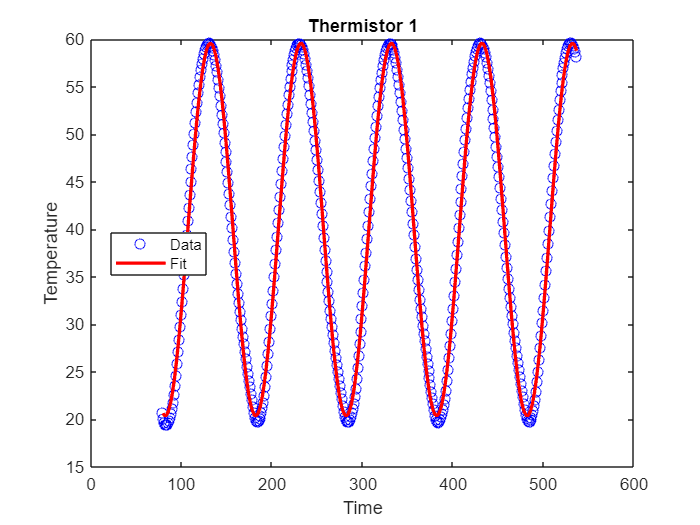

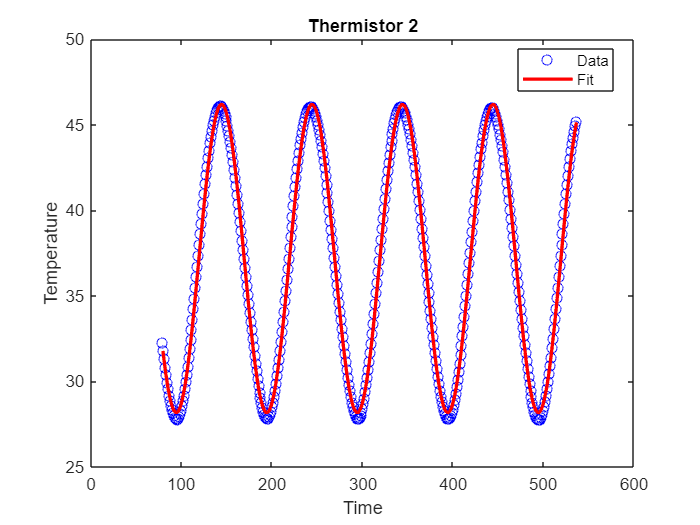

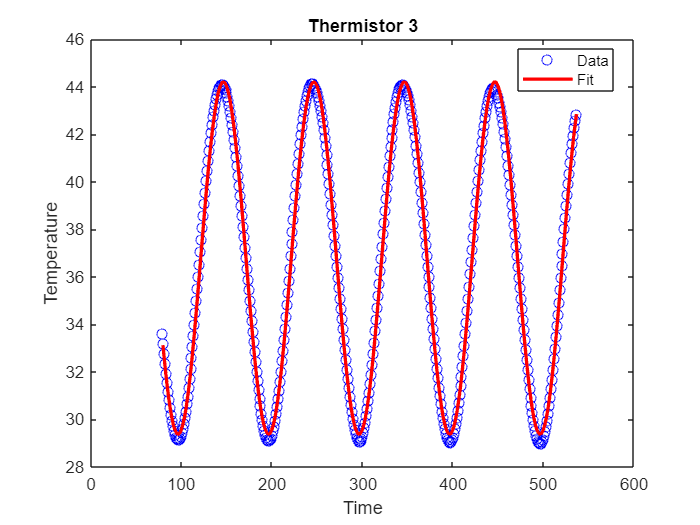

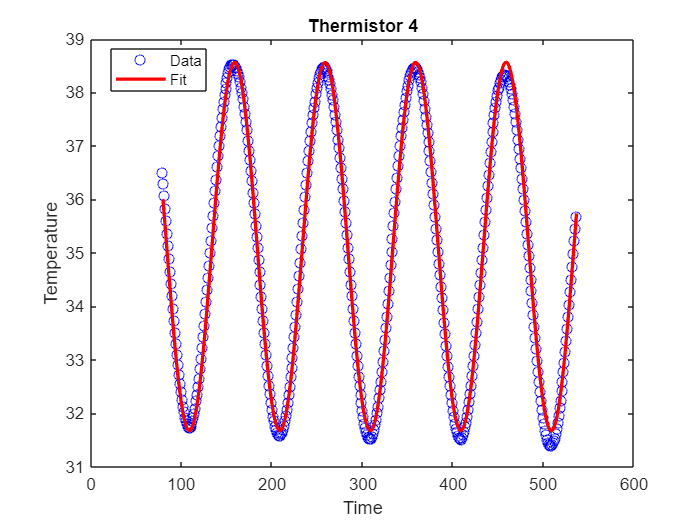

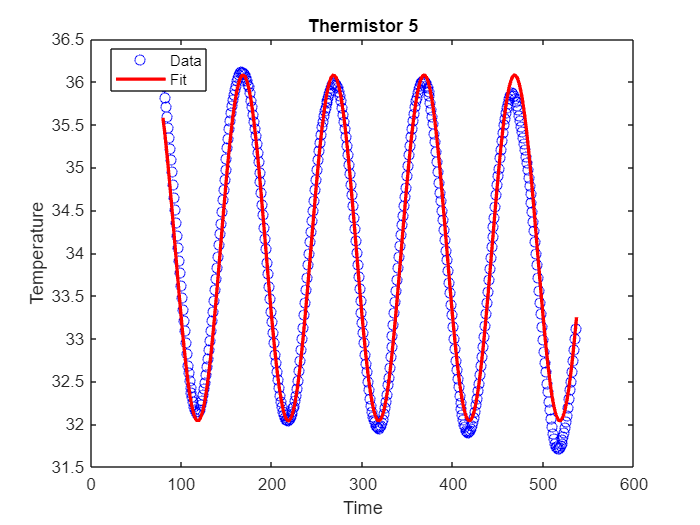

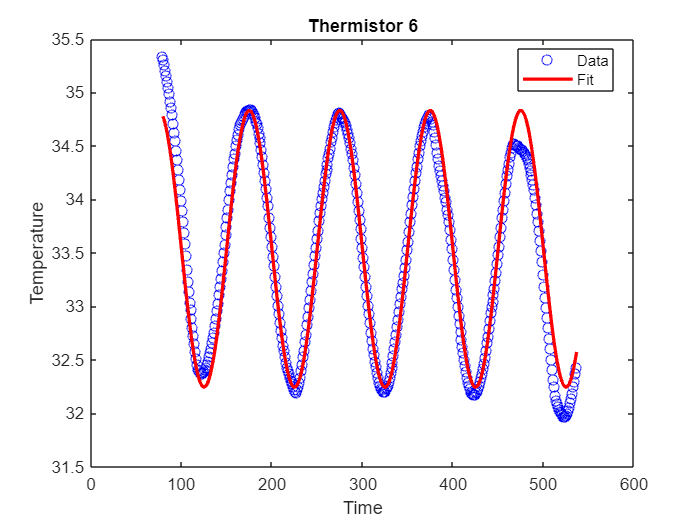

% Assuming you have fitted the data for each thermistor as AngFit{i}

% Iterate through each thermistor's data and fit
for i = 1:6
    figure;  % Create a new figure for each pair of data and fit

    % Plot the data points
    plot(time, tempDataInRange(:, i), 'bo', 'DisplayName', 'Data');
    hold on;

    % Calculate the fit values based on the model
    A = AngFit{i}.A;
    B = AngFit{i}.B;
    epsilon = AngFit{i}.epsilon;

    % Generate the fit curve using the model
    fitCurve = A + B * cos(w * time + epsilon);

    % Plot the fit curve
    plot(time, fitCurve, 'r-','LineWidth', 2, 'DisplayName', 'Fit');

    % Label the plot
    title(['Thermistor ' num2str(i)]);
    xlabel('Time');
    ylabel('Temperature');
    legend('Location', 'best');

    hold off;
end

Fit the $A_i$


$$
A_i = 
(T_0-T_{\infty }) e^{- q_l (x_i + \delta) } = T  e^{- q_l (x_i + \delta) } \text{ with }

q_l=\sqrt{\frac{\nu }{\kappa }}$$


The fitting parameters are $T,q_l$, and $\delta$.

For now, $\delta =0$.

The data in AngFit{1}.A is the TEC. We will use the three values AngFit{2}.A, AngFit{3}.A and AngFit{4}.A

The locations of these thermistors are at x = 0, 12.7 mm, and 25.4 mm along the rod. We consider the location of the first measurment thermistor to define x = 0. 

% Define the equation expression for the fit
%fitEqA = fittype('T * exp(-(ql * (x + del)) )', 'independent', 'x','coefficients', {'T', 'ql', 'del'});
fitEqA = fittype('T * exp(-(ql * (x)) )', 'independent', 'x','coefficients', {'T', 'ql'});

% locations of thermistors
x = [0 12.7e-3 50.8e-3 76.2e-3 101.6e-3]'

x =          0
    0.0127
    0.0508
    0.0762
    0.1016


Aarray = [AngFit{2}.A AngFit{3}.A AngFit{4}.A AngFit{5}.A AngFit{6}.A]'

Aarray =    37.1771
   36.7886
   35.1226
   34.0594
   33.5391



% Fit  vs. x 

[AFit, Agof] = fit(x, Aarray, fitEqA, 'StartPoint', [43 4]);

% Display the results
disp('Fitted Parameters:');

Fitted Parameters:


disp(['T: ', num2str(AFit.T)]);

T: 37.1815


disp(['ql: ', num2str(AFit.ql)]);

ql: 1.0713


%disp(['del: ', num2str(AFit.del)]);

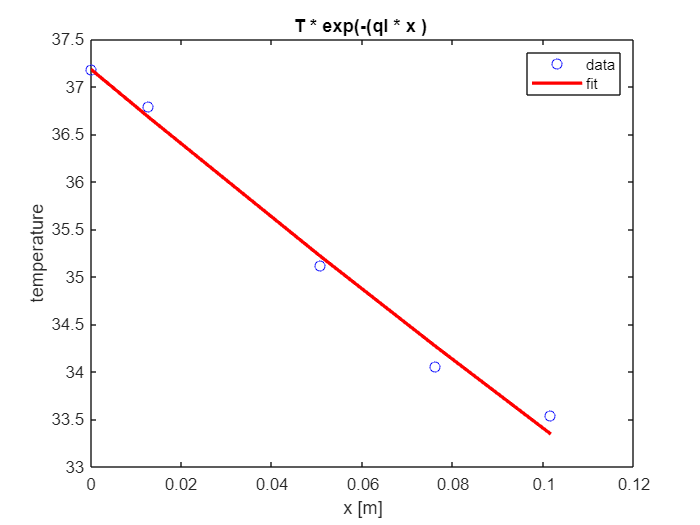

% plot the data and fit

    % Plot the data points
    plot(x, Aarray, 'bo', 'DisplayName', 'Data');
    hold on;

    % Calculate the fit values based on the model
    T = AFit.T;
    ql = AFit.ql;
%    del = AFit.del;

    % Generate the fit curve using the model
    fitCurve = T * exp(-(ql * (x)) );

    % Plot the fit curve
    plot(x, fitCurve, 'r-','LineWidth', 2, 'DisplayName', 'Fit');

    % Label the plot
    title(['T * exp(-(ql * x ) ']);
    xlabel('x [m]');
    ylabel('temperature');
    legend('data', 'fit');

    hold off;

Fit the $B_i$

$B_i = 

\text{$\Delta $T} e^{ -q x_i + \delta}

\text{ with }

q=\sqrt{\frac{\sqrt{\nu ^2+\omega ^2}+\nu }{2 \kappa }}$, 

The fitting parameters are $\Delta T\;\textrm{and}\;q$.

For now, $\delta =0$.

The data in AngFit{1}.B is the TEC. We will use the three values AngFit{2}.B, AngFit{3}.B and AngFit{4}.B

The locations of these thermistors are at x = 0, 12.7 mm, and 25.4 mm along the rod. We consider the location of the first measurment thermistor to define x = 0. 

% Define the equation expression for the fit
%fitEqA = fittype('T * exp(-(ql * (x + del)) )', 'independent', 'x','coefficients', {'T', 'ql', 'del'});
fitEqB = fittype('T * exp(-(q * (x)) )', 'independent', 'x','coefficients', {'T', 'q'});

% locations of thermistors
%x = [12.7e-3 25.4e-3 63.5e-3 88.9e-3 114.3e-3]'
x = [0 12.7e-3 50.8e-3 76.2e-3 101.6e-3]'

x =          0
    0.0127
    0.0508
    0.0762
    0.1016


Barray = [AngFit{2}.B AngFit{3}.B AngFit{4}.B AngFit{5}.B AngFit{6}.B]'

Barray =     9.0008
    7.4050
    3.4413
    2.0196
    1.2930



% Fit  vs. x 

[BFit, Bgof] = fit(x, Barray, fitEqB, 'StartPoint', [10 2]);

% Display the results
disp('Fitted Parameters:');

Fitted Parameters:


disp(['Del T: ', num2str(BFit.T)]);

Del T: 9.1507


disp(['q: ', num2str(BFit.q)]);

q: 19.1678


%disp(['del: ', num2str(AFit.del)]);

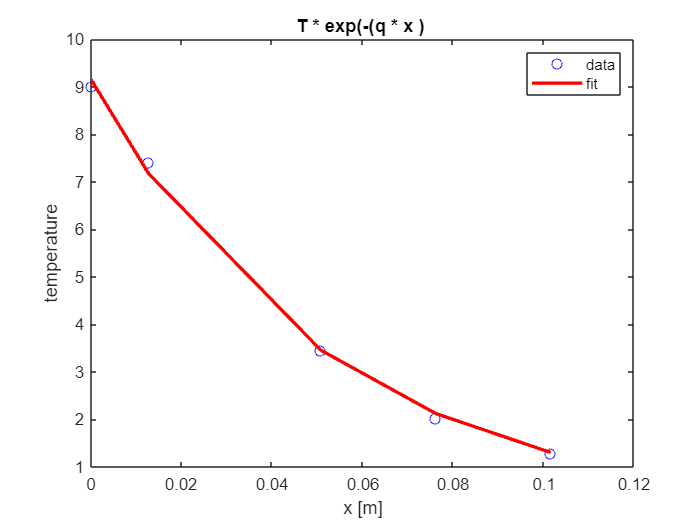

% plot the data and fit

    % Plot the data points
    plot(x, Barray, 'bo', 'DisplayName', 'Data');
    hold on;

    % Calculate the fit values based on the model
    T = BFit.T;
    q = BFit.q;
%    del = AFit.del;

    % Generate the fit curve using the model
    fitCurve = T * exp(-(q * (x)) );

    % Plot the fit curve
    plot(x, fitCurve, 'r-','LineWidth', 2, 'DisplayName', 'Fit');

    % Label the plot
    title(['T * exp(-(q * x ) ']);
    xlabel('x [m]');
    ylabel('temperature');
    legend('data', 'fit');

    hold off;

Fit the $\varepsilon_i$.

$\epsilon_i = \epsilon -q' x_i 

\text{ with }

q'=\sqrt{\frac{\sqrt{\nu ^2+\omega ^2}-\nu }{2 \kappa }}$.  

The data in AngFit{1}.epsilon is at the TEC. We will use the three values AngFit{2}.epsilon, AngFit{3}.epsilon and AngFit{4}.epsilon

The locations of these thermistors are at x = 0, 12.7 mm, and 25.4 mm along the rod. We consider the location of the first measurment thermistor to define x = 0. 

  % Define the equation expression for the fit
fitEqEpsilon = fittype('epsi - qp * x', 'independent', 'x','coefficients', {'epsi', 'qp'});

% locations of thermistors
x = [0 12.7e-3 50.8e-3 76.2e-3 101.6e-3]'

x =          0
    0.0127
    0.0508
    0.0762
    0.1016


Epsilonarray = [AngFit{2}.epsilon AngFit{3}.epsilon AngFit{4}.epsilon AngFit{5}.epsilon AngFit{6}.epsilon]'

Epsilonarray =     3.5019
    3.3763
    2.5992
    2.0065
    1.5768



% Fit  vs. x 

[EpsilonFit, Epsilongof] = fit(x, Epsilonarray, fitEqEpsilon, 'StartPoint', [3.5 40]);

% Display the results
disp('Fitted Parameters:');

Fitted Parameters:


disp(['eps: ', num2str(EpsilonFit.epsi)]);

eps: 3.5625


disp(['qp: ', num2str(EpsilonFit.qp)]);  

qp: 19.6917


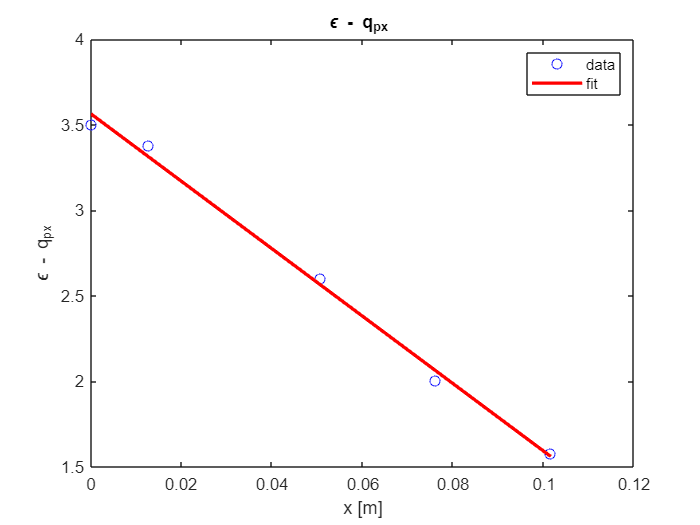

% plot the data and fit

    % Plot the data points
    plot(x, Epsilonarray, 'bo', 'DisplayName', 'Data');
    hold on;

    % Calculate the fit values based on the model
    epsi = EpsilonFit.epsi;
    qp = EpsilonFit.qp;


    % Generate the fit curve using the model
    fitCurve = epsi - qp * x;

    % Plot the fit curve
    plot(x, fitCurve, 'r-','LineWidth', 2, 'DisplayName', 'Fit');

    % Label the plot
    title(['\epsilon - q_px ']);
    xlabel('x [m]');
    ylabel('\epsilon - q_px');
    legend('data', 'fit');

    hold off;


$$q q'=\frac{\omega }{2 \kappa }$$



$$\kappa = \frac{\omega}{2 q q'}$$


$\kappa =\frac{k}{c \rho } \left[\frac{M^2}{\text{sec}}\right]$  thermal diffusion constant

$k\;\left\lbrack \frac{\mathrm{W}}{\mathrm{M}\;\mathrm{K}}\right\rbrack$thermal conductivity


$$k = \kappa c \rho =  \frac{\omega c \rho}{2 q q'}$$


#### values for aluminum

$\rho =2700\;\left\lbrack \frac{\textrm{kg}}{{\mathrm{M}}^3 }\right\rbrack \;\;\;$density

$c=900\;\left\lbrack \frac{J}{K\;\textrm{kg}}\right\rbrack$   specific heat

$d=\frac{1}{2\;}\textrm{inch}$ diameter

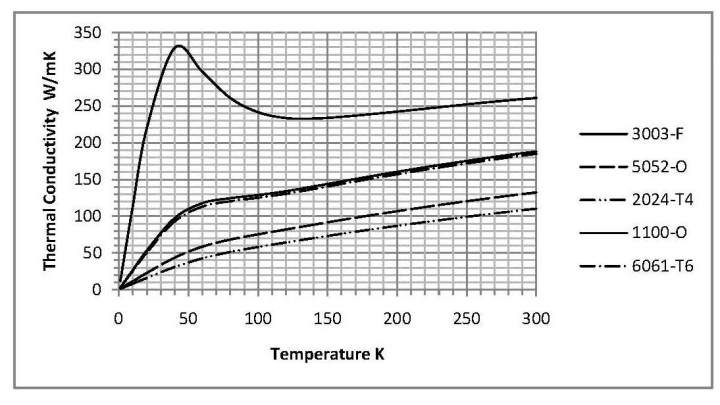

Thermal conductivity for several aluminum alloys.

w = 2*pi/period;  % frequence in radians / sec
c = 900; % specific heat
rho = 2700; % density
k = w*c*rho/(2*q*qp); % [W/M*K]
disp(['thermal conductivity k [W/M*K]: ', num2str(k)]);  

thermal conductivity k [W/M*K]: 202.2551
